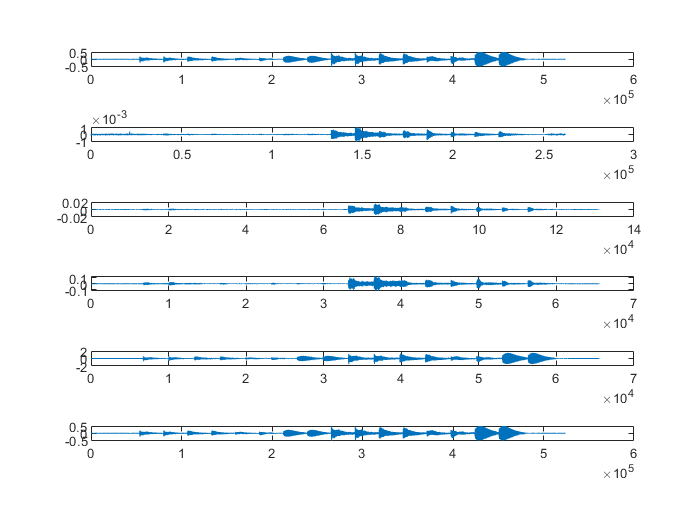

%声音信号的傅氏变换
% [x,fs]=audioread('tada.wav'); 
% fx=fft(x);
% plot(abs(fftshift(fx)));
% xlabel('Time');
% ylabel('Amplitude');
% title('The Wave form of signal');
% grid on; 
%小波变换
% [a,fs]=audioread('piano.wav'); 
% [ca1,cd1]=dwt(a(:,1),'db4');%近似，细节
% a0=idwt(ca1,cd1,'db4',length(a(:,1)));
% subplot(4,1,1);plot(a(:,1));
% subplot(4,1,2);plot(cd1);
% subplot(4,1,3);plot(ca1);
% subplot(4,1,4);plot(a0);
%语音信号小波变换三级分解
[a,fs]=audioread('piano.wav'); 
[c,l]=wavedec(a(:,2),3,'db4');
ca3=appcoef(c,l,'db4',3);%提取第3层的近似系数
cd3=detcoef(c,l,3);%提取第3层的细节系数
cd2=detcoef(c,l,2);
cd1=detcoef(c,l,1);
a0=waverec(c,l,'db4');

subplot(6,1,1);plot(a(:,2));
subplot(6,1,2);plot(cd1);
subplot(6,1,3);plot(cd2);
subplot(6,1,4);plot(cd3);
subplot(6,1,5);plot(ca3);
subplot(6,1,6);plot(a0);

% 离散余弦变换
% len=40000;
% [fn,pn]=uigetfile('* .wav','请选择音频文件')
% [x,fs]=wavread(strcat(pn,fn),len);
% xsync=idct(xf);
% [row,col]=size(x);
% xff=zeros(row,col);
% xff(1:row,1:col)=xf(1:row,1:col);
% y=idct(xff);
% clear;
% [x,fs]=audioread('piano.wav');
% len=40000;
% f1=[0:len-1]*fs/len;
% xf=dct(x);
% figure;
% subplot(2,1,1);plot(x);title('original audio');
% subplot(2,1,2);plot(abs(xf));title('DCT');
